# ```````Explore Mask Usage Data

Here, we include mask survey data with the locations and cases. Visualize, analyze, join with the county data and prepare for predictive modeling.

Load data if not already in workspace.  

load mergedCountyData totalcounty  
load Data/usDataLocations.mat uscounties
head(totalcounty)

ans = 8×18 table
    county      state     fips    GroupCount    cases    deaths    abbrev    POPESTIMATE2019    DEATHS2019      LON       LAT      NEVER    RARELY    SOMETIMES    FREQUENTLY    ALWAYS    casesbypop    deathsbypop
    _______    _______    ____    __________    _____    ______    ______    _______________    __________    _______    ______    _____    ______    _________    __________    ______    

this includes merged data with masks usage data from Data/mask-use.

## Explore mask usage overall

Explore overall summary stats

msklbl = ["NEVER","RARELY","SOMETIMES","FREQUENTLY","ALWAYS"];
masks = totalcounty(:,["county","abbrev","fips",msklbl]);
summary(masks(:,msklbl))

Variables:
    NEVER: 3276×1 double
        Values:
            Min             0      
            Median          0.068  
            Max             0.432  
            NumMissing      143    
    RARELY: 3276×1 double
        Values:
            Min             0      
            Median          0.073  
            Max             0.384  
            NumMissing      143    
    SOMETIMES: 3276×1 double
        Values:
            Min             0.001  
            Median          0.116  
            Max             0.422  
            NumMissing      143    
    FREQUENTLY: 3276×1 double
        Values:
            Min             0.029  
            Median          0.204  
            Max             0.549  
            NumMissing      143    
    ALWAYS: 3276×1 double
        Values:
            Min             0.115  
            Median          0.497  
            Max             0.889  
    

Determine average overall mask usage.

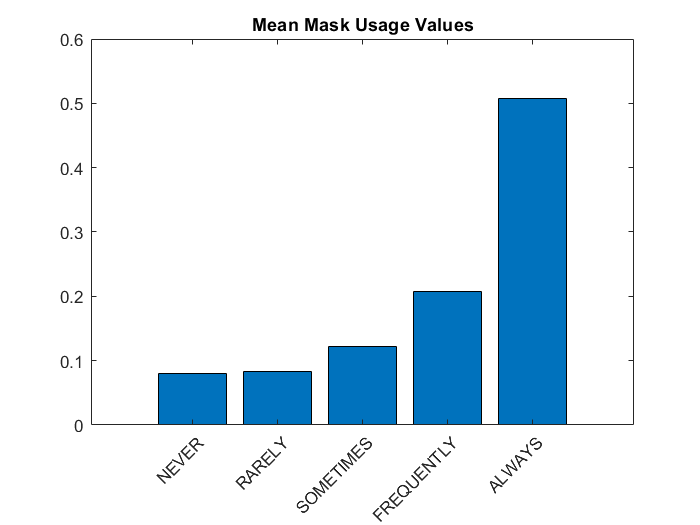

m = mean(masks{:,msklbl},"omitnan");
bar(m)
xticklabels(msklbl)
xtickangle(45)
title("Mean Mask Usage Values")

Look at histograms of mask values. Use a gradient to shade the bars.

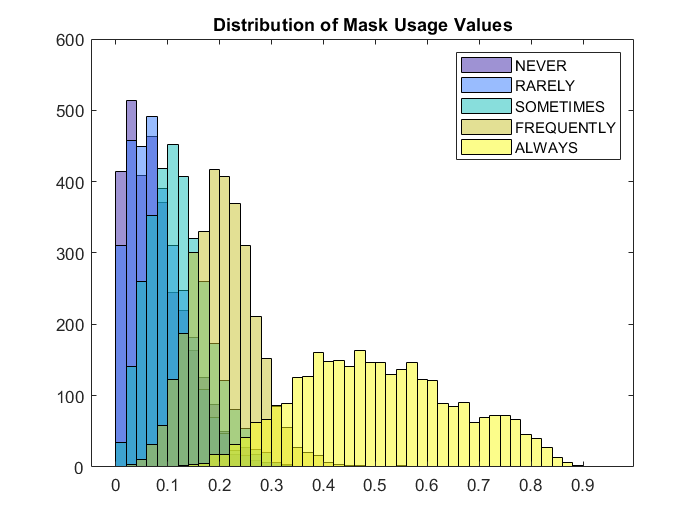

colorvals = parula(5);
opts = {"BinWidth",0.02,"BinLimits",[0 0.95],"FaceAlpha",0.5,...
    "FaceColor"};
figure
histogram(masks.NEVER,opts{:},colorvals(1,:))
hold on
for ii = 2:5
    histogram(masks.(msklbl(ii)),opts{:},colorvals(ii,:))
end
hold off
legend(msklbl)
title("Distribution of Mask Usage Values")

## Compare mask and county case data

countyMasks = totalcounty;

Look at top usage and compare

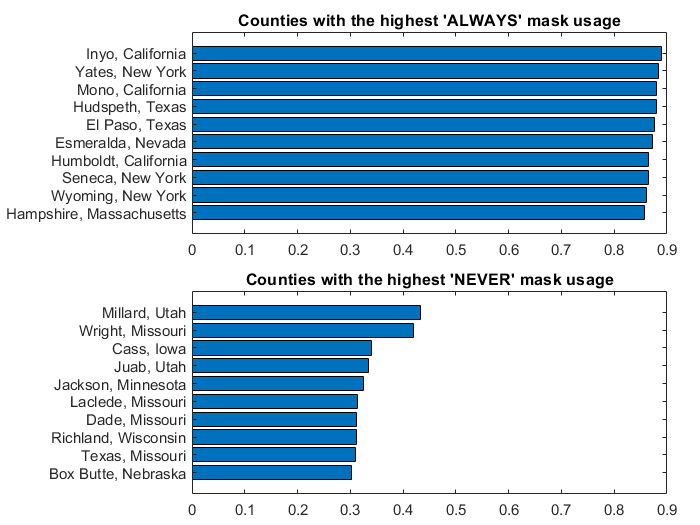

tiledlayout(2,1,"Padding","compact","TileSpacing","compact");
nexttile
tal = topkLocations(countyMasks,10,"ALWAYS");
title("Counties with the highest 'ALWAYS' mask usage")
xl = xlim;
nexttile
tnev = topkLocations(countyMasks,10,"NEVER");
title("Counties with the highest 'NEVER' mask usage")
xlim(xl)  % Use same xlimits for comparison

Look at high cases and high "NEVER" mask usage.

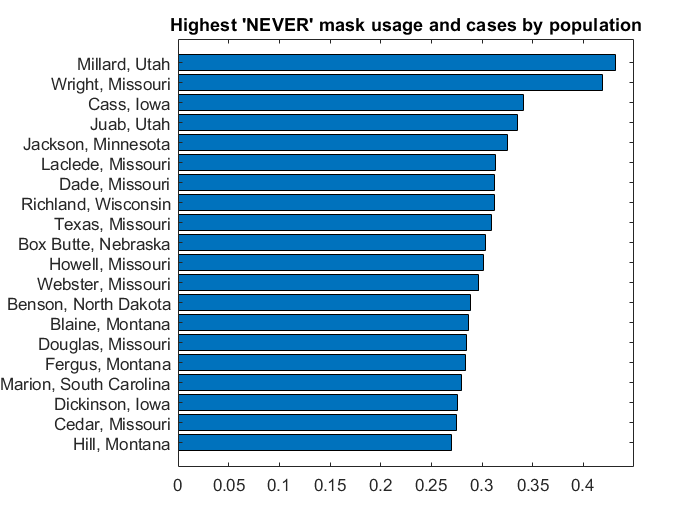

figure
neverhighcases = topkLocations(countyMasks,20,["NEVER","casesbypop"]);
title("Highest 'NEVER' mask usage and cases by population")

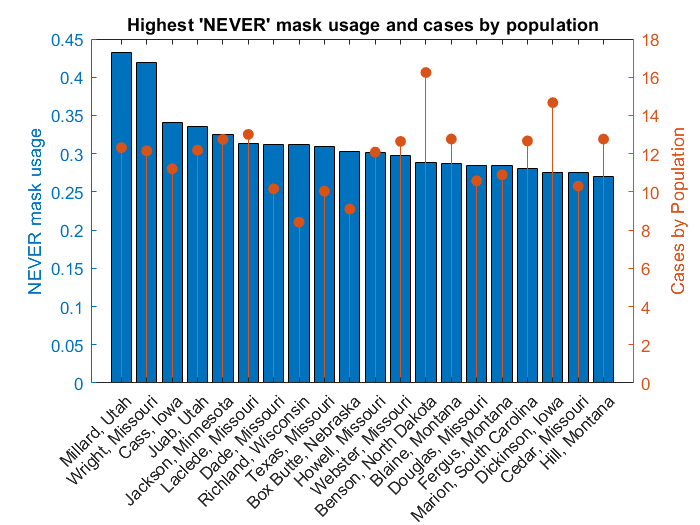

figure
yyaxis left
bar(neverhighcases.NEVER)
ylabel("NEVER mask usage")
yyaxis right
stem(neverhighcases.casesbypop,"filled")
ylabel("Cases by Population")
xticklabels(neverhighcases.loc)
xtickangle(45)
xticks(1:length(neverhighcases.loc))
title("Highest 'NEVER' mask usage and cases by population")

Get more values for summary stats comparisons

topnever = topkrows(countyMasks,100,"NEVER");
topalways = topkrows(countyMasks,100,"ALWAYS");

Average cases by pop and compare to top ones

avgcasesbypop = mean(countyMasks.casesbypop,"omitnan")

avgcasesbypop = 11.1066

topneveravg = mean(topnever.casesbypop,"omitnan")

topneveravg = 12.2929

topalwaysavg = mean(topalways.casesbypop,"omitnan")

topalwaysavg = 8.8474

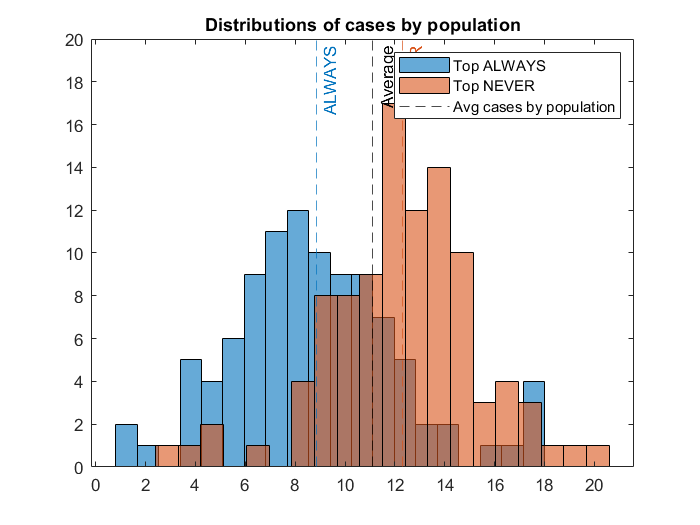

figure
histogram(topalways.casesbypop,20)
hold on
histogram(topnever.casesbypop,20)
xline(avgcasesbypop,"k--","Average")
xline(topalwaysavg,"--","ALWAYS","Color",[0 0.4470 0.7410])
xline(topneveravg,"--","NEVER","Color",[0.8500 0.3250 0.0980])
hold off
legend("Top ALWAYS","Top NEVER","Avg cases by population")
title("Distributions of cases by population")
ylim([0 20])

The histogram and averages seem to show a higher rate of cases for higher "NEVER" ratings.

Do some locations have more NEVER mask usage compared to other values? (could compare all variables but start with always)

nevermore = countyMasks(countyMasks.NEVER > countyMasks.ALWAYS,:)

nevermore = 30×18 table
     county       state      fips     GroupCount    cases    deaths    abbrev    POPESTIMATE2019    DEATHS2019      LON       LAT      NEVER    RARELY    SOMETIMES    FREQUENTLY    ALWAYS    casesbypop    deathsbypop
    _________    ________    _____    __________    _____    ______    ______    _______________    __________    _______    ______    _____    ______    _________    __________    ______

nevermoreavg = mean(nevermore.casesbypop)

nevermoreavg = 12.3309

avgcasesbypop

avgcasesbypop = 11.1066

topneveravg

topneveravg = 12.2929

Other visuals of cases, usage for comparison

vars = ["casesbypop",msklbl]; %[11,13:17]; 
varlbls = string(countyMasks.Properties.VariableNames(vars));

Lets take a look at correlations between cases and mask ratings

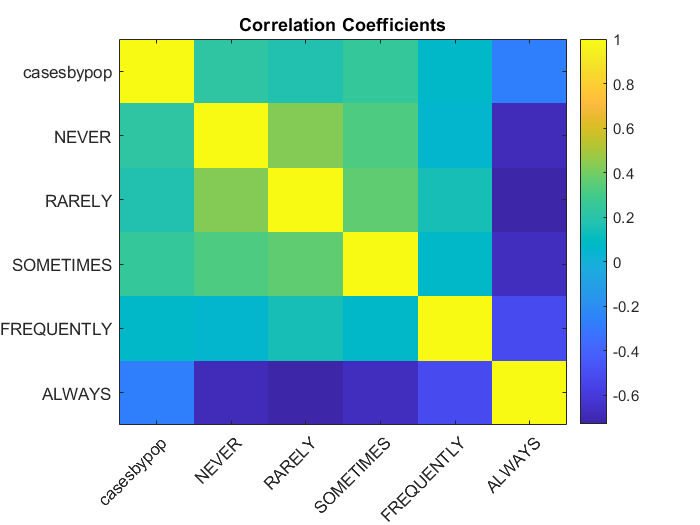

c = corr(countyMasks{:,vars},"rows","pairwise");
imagesc(c)
colorbar
xticklabels(varlbls)
xtickangle(45)
yticklabels(varlbls)
title("Correlation Coefficients")

The "ALWAYS" usage is least correlated w/ the others. Others have higher corr coeffs with cases by population.

## Overall mask usage by state

Avg by state - use median less sensitive to outliers

mdMaskByState = groupsummary(countyMasks,"state","median",["casesbypop",msklbl])

mdMaskByState = 55×8 table
           state            GroupCount    median_casesbypop    median_NEVER    median_RARELY    median_SOMETIMES    median_FREQUENTLY    median_ALWAYS
    ____________________    __________    _________________    ____________    _____________    ________________    _________________    _____________
    Alabama                     67             12.821              0.077           0.074              0.136               0.201              0.466    
    Alaska                      30             8.8497              0.048           0.051              0.067               0.316              0.413    
    Arizona                     16             13.248              0.039           0.063         

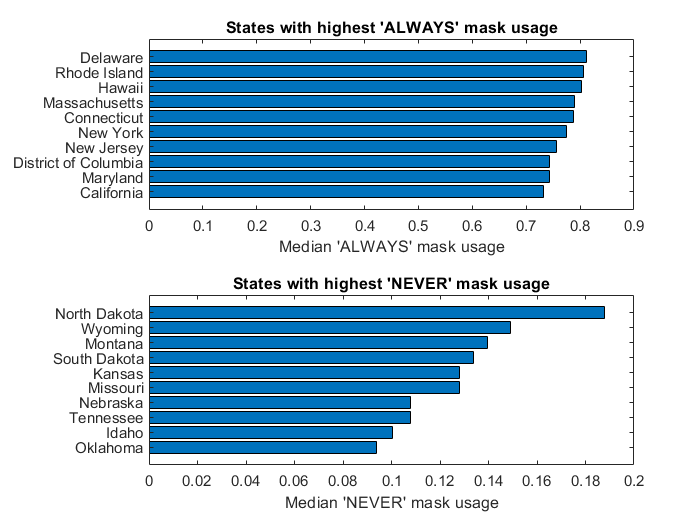

tiledlayout("flow");
nexttile
topkLocations(mdMaskByState,10,"median_ALWAYS");
title("States with highest 'ALWAYS' mask usage")
xlabel("Median 'ALWAYS' mask usage")
nexttile
topkLocations(mdMaskByState,10,"median_NEVER");
title("States with highest 'NEVER' mask usage")
xlabel("Median 'NEVER' mask usage")

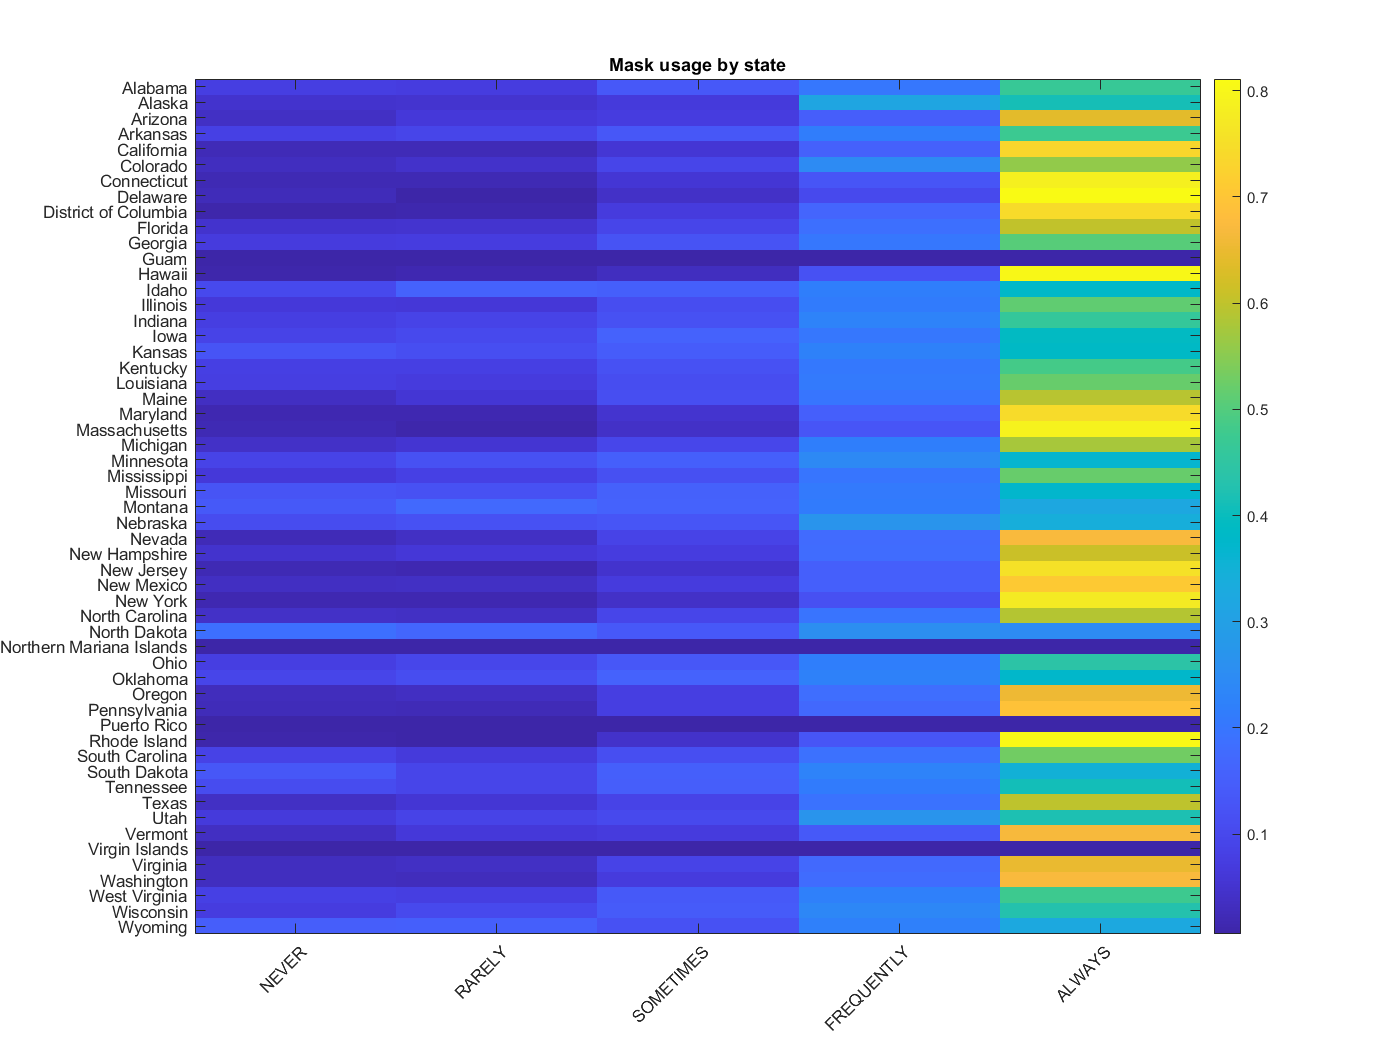

bigFigure;
imagesc(mdMaskByState{:,4:end})
colorbar
yticks(1:length(mdMaskByState.state))
yticklabels(mdMaskByState.state)
xticks(1:5)
xticklabels(msklbl)
xtickangle(45)
title("Mask usage by state")

## Make rating based on usage data

Penalize the bad mask values, middle neutral, reward good mask values

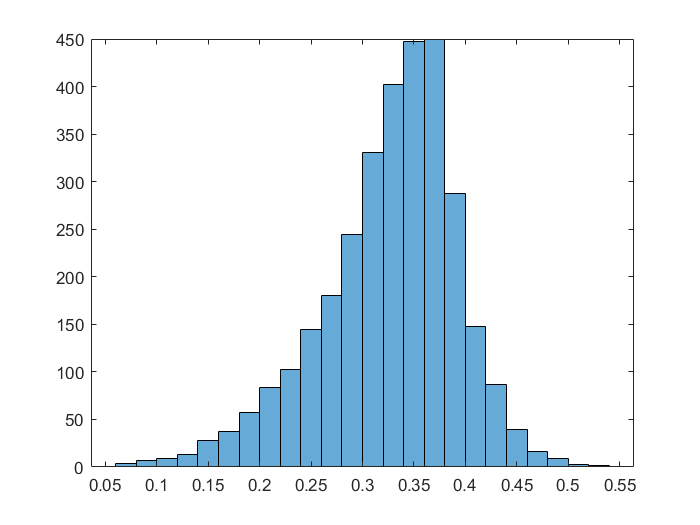

f = [-3 -2 1 2 3];
scaling = countyMasks{:,msklbl} ./ f;
rating = sum(scaling,2);
figure
histogram(rating)

mean(rating,"omitnan")

ans = 0.3263

median(rating,"omitnan")

ans = 0.3362

[mi,ma] = bounds(rating)

mi = 0.0630

ma = 0.5382

Make it categorical w 5 levels

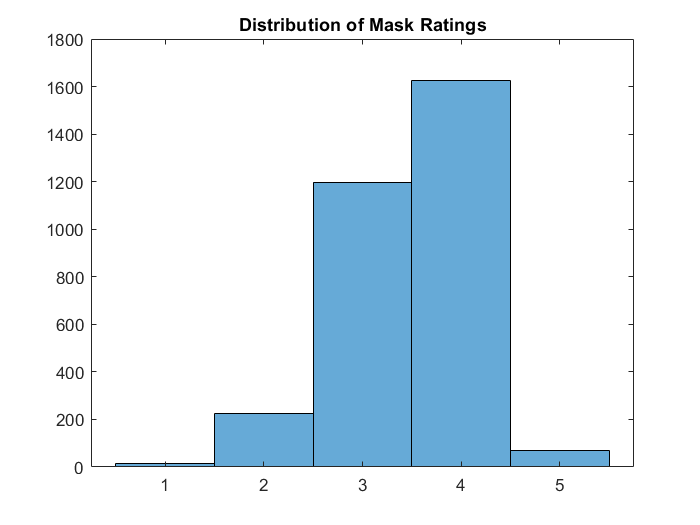

countyMasks.MaskRating = discretize(rating,5);
histogram(countyMasks.MaskRating)
xticks(1:5)
title("Distribution of Mask Ratings")

It's not distributed evenly, but we could force the edges and make it more even. We'll return to this if needed.

Examine cases by population based on rating.

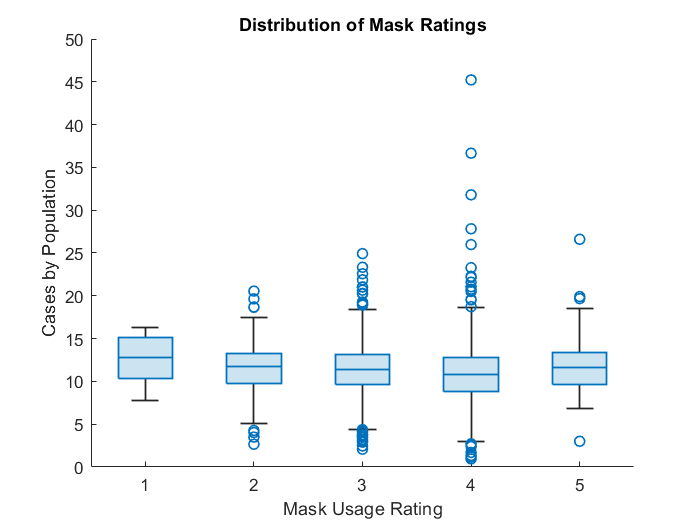

boxchart(countyMasks.MaskRating,countyMasks.casesbypop)
xticks(1:5)
ylabel("Cases by Population")
xlabel("Mask Usage Rating")
title("Distribution of Mask Ratings")

Again, we might want to change the bins instead of making them even in this case.. notice many outliers in 3 and 4. Currently, we'll only use it for visualizations, so let's move on.

## Visualize based on mask rating

Lets try a parallelplot to see if there are any patterns.

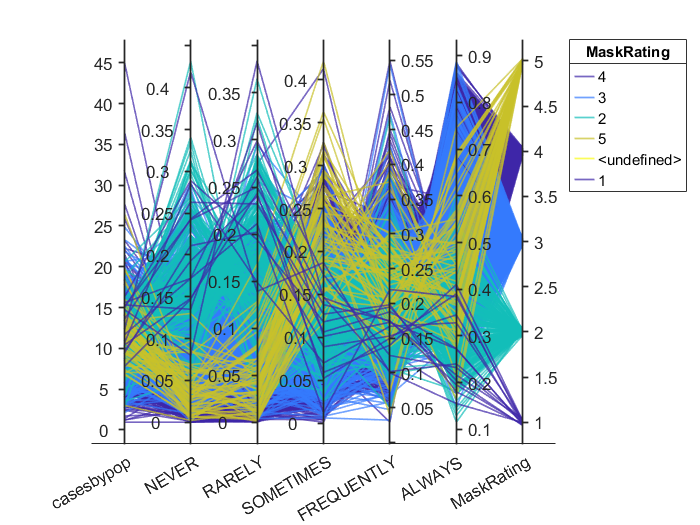

parallelplot(countyMasks(:,[vars,"MaskRating"]),"GroupVariable","MaskRating","Color",colorvals)

Visualize on the map.

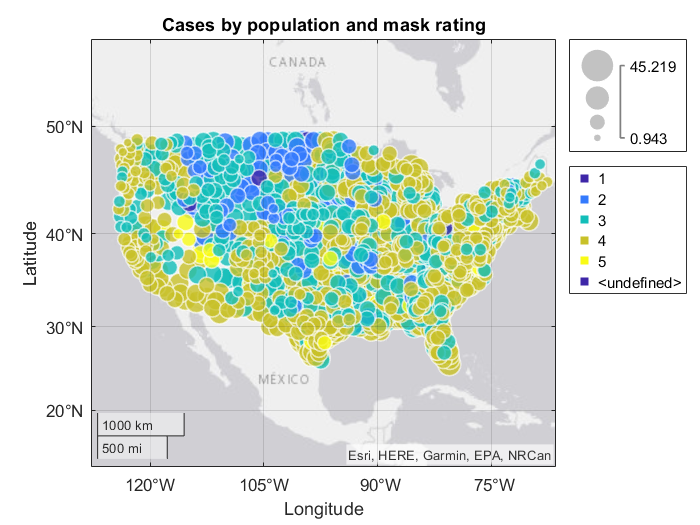

geobubble(countyMasks.LAT,countyMasks.LON,...
    countyMasks.casesbypop,categorical(countyMasks.MaskRating),...
    "BubbleColorList",colorvals);
geolimits([16.0 55.0],[-127.8 -66.5])
title("Cases by population and mask rating");

Use geoscatter to apply transparency to the bubbles.

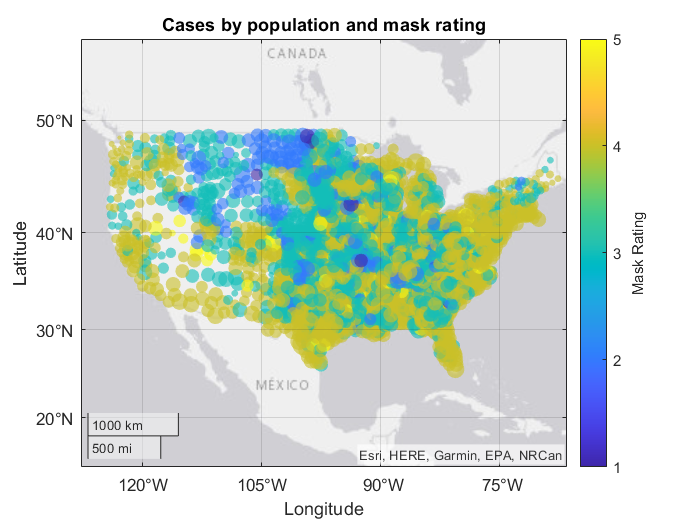

r = rescale(countyMasks.casesbypop,5,250);
geoscatter(countyMasks.LAT,countyMasks.LON,r,countyMasks.MaskRating,"filled",...
    "MarkerFaceAlpha",0.6); 
geolimits([16.0 55.0],[-127.8 -66.5])
colormap parula
cb = colorbar("Ticks",1:5);
cb.Label.String = "Mask Rating";
title("Cases by population and mask rating")

Join this info with the time series data by county (outerjoin `uscounties` and `countyMasks`)

% Join tables
allCountyData = outerjoin(uscounties,countyMasks,"Keys",["county","state",...
    "fips"]);
head(allCountyData)

ans = 8×24 timetable
       date       county_uscounties    state_uscounties    fips_uscounties    cases_uscounties    deaths_uscounties    county_countyMasks    state_countyMasks    fips_countyMasks    GroupCount    cases_countyMasks    deaths_countyMasks    abbrev    POPESTIMATE2019    DEATHS2019      LON       LAT      NEVER    RARELY    SOMETIMES    FREQUENTLY    ALWAYS    casesbypop    deathsbypop    MaskRating
    __________    _________________    ________________    _______________    _

Its alot of repeated but useful since you want to see the trends and we'll use this for machine learning purposes.

allCountyData = removevars(allCountyData,["cases_countyMasks","deaths_countyMasks","GroupCount"]); 
allCountyData.Properties.VariableNames = erase(allCountyData.Properties.VariableNames,"_uscounties");
allCountyData = sortrows(allCountyData);
allCountyData.casesbypop = allCountyData.cases./allCountyData.POPESTIMATE2019;  % calculate cases by pop for that day

Create another plot to visualize how things change over time based on mask usage and save as a .gif (do this in command window)

% overTimeGif(allCountyData,["casesbypop","MaskRating"],"map","Cases by Population and Mask Usage",10,"mapbyrating.gif");

## Save the results

save Data/allCountyData allCountyData

Prep for machine learning and use in app.

prepCountyMasks
head(countyMasks,5)

ans = 5×21 table
     county          state         fips     GroupCount    totalcases    deaths    abbrev    POPESTIMATE2019    DEATHS2019      LON       LAT      NEVER    RARELY    SOMETIMES    FREQUENTLY    ALWAYS    casesbypop    deathsbypop    MaskRating        cases          min_date 
    _________    ______________    _____    __________    __________    ______    ______    _______________    __________    _______    ______    _____

save Data/countyMasks countyMasks

## Use machine learning to predict cases

Now lets do some clustering and modeling to predict cases based on the information we have.

edit PredModelingApproaches.mlx